% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Tamaño de representación
Nx = 2048;
Ny = 2048;

% Condiciones de Muestreo
dx =6.513*mm/Nx;
dy = dx;

lambda = 633*nm;
k=(2*pi)/lambda;

distPropagacion=73*mm

distPropagacion = 0.0730


zlim=Nx*dx^2/lambda %Se decide usar Transformada de fresnel

zlim = 0.0327

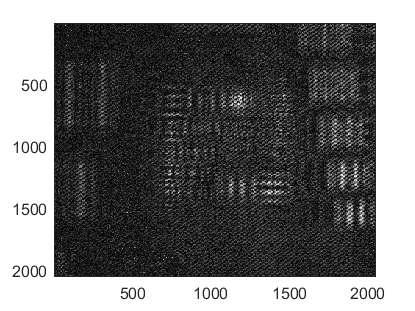


%Leer la imagen del holograma
ImHolo=imread("Hologram.tiff");%Pixeles de 2048*2048
ImHolo=imresize(ImHolo,1);
ImHolo=im2double(ImHolo);
prom = mean2(ImHolo);
ImSinMedia = ImHolo;
imagesc(ImHolo)
colormap("gray");

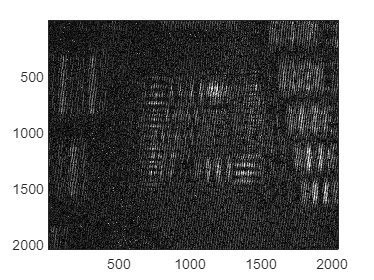

imagesc(ImSinMedia)
colormap("gray");

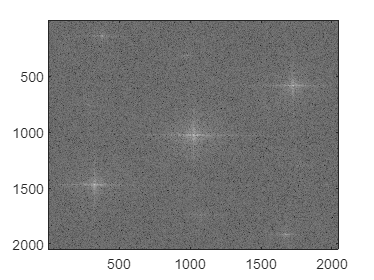




%Sacar transformada de Fourier del holograma
FourierTransform=fft2(ImSinMedia);
FFTHOLO = (fftshift(fft2(ImSinMedia)));
Transformada=imagesc(log(abs(fftshift(FourierTransform))));


% Se sacan los máximos
[maximosY,maximosX] = find(abs(FFTHOLO) == max(abs(FFTHOLO),[],"all"))

maximosY = 1025

maximosX = 1025

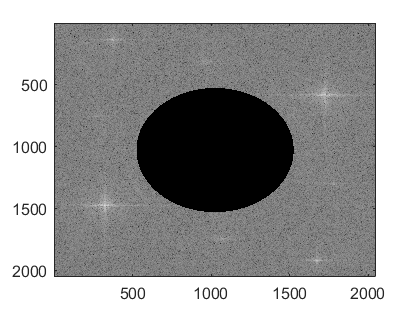


%Como el máximo central es el de mayor intensidad se elimina con un filtro
%para buscar los otros dos máximos

FFTHoloSinCentro = FFTHOLO.*(~filtroCircular([1025 1025],500,size(FFTHOLO)));
imagesc(log10(abs(FFTHoloSinCentro)))


%Deben encontrarse los dos máximos que dan cuenta de la información del
%objeto y onda de referencia

[maximosY1,maximosX1] = find(abs(FFTHoloSinCentro) == max(abs(FFTHoloSinCentro),[],"all"))

maximosY1 =         1469
         581


maximosX1 =          324
        1726


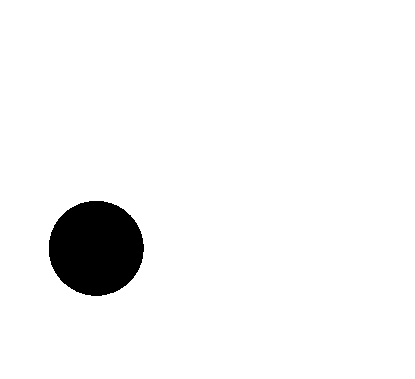


%Creación de la máscara para la selección de un orden

Mascara1= (~filtroCircular([324 1469],300,size(FFTHOLO)));
imshow(Mascara1);

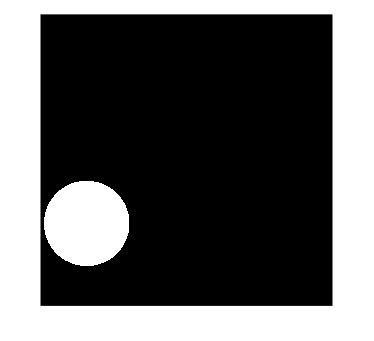

Filtro1 = imcomplement(Mascara1); 
imshow(Filtro1)

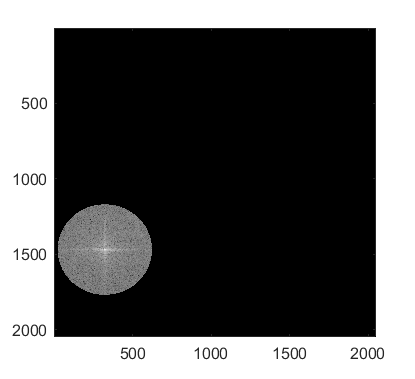


%Creación de máscara para selección de orden menos1
Mascara2= (~filtroCircular([1726 581],300,size(FFTHOLO)));
Filtro2 = imcomplement(Mascara2); 

%Multiplicación máscara para orden menos 1
OrdenMenos=FFTHOLO.*Filtro2;
InversaMenos=fftshift(ifft2(OrdenMenos));

%Translación de orden menos al centro
OrdenMenosCentrado = imtranslate(OrdenMenos,[1025-1726, 1025-581],'FillValues',0);
InversaCentroOrdenMenos=fftshift(ifft2(OrdenMenosCentrado));

%Se multiplica la transformada por la máscara para obtener un solo orden
OrdenMas=FFTHOLO.*Filtro1;
imagesc(log(abs((OrdenMas).^2)))

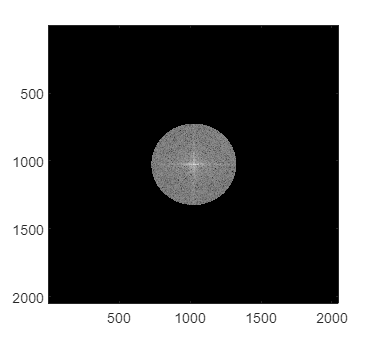

Angulos = angle(FFTHOLO);

ImOrdenMas = imag(OrdenMas);
ReOrdenMas = real(OrdenMas);

angleX1=acos(lambda/(4*dx));
angleY1=acos(lambda/(4*dy));

Onda1= plane_wave2D(Nx, Ny, angleX1, angleY1, dx, dy, k);
campoEntrada1=OrdenMas.*Onda1;

campoEntrada1 = imtranslate(campoEntrada1,[1025-324, 1025-1469],'FillValues',0);
imagesc(log(abs((campoEntrada1)).^2))

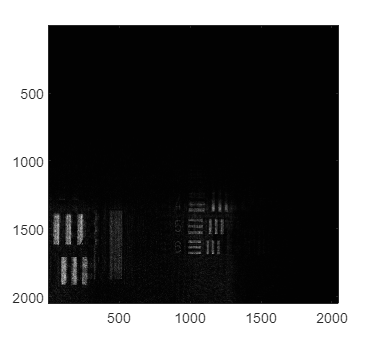

% campoEntrada2 = ifft2(campoEntrada1);
% imagesc((abs((campoEntrada2)).^2))

campoPrueba1 = ImHolo.*Onda1;


%c1=transformadaFresnel(campoPrueba1,dx,dy,distPropagacion, lambda, "zoom", true);
%c2=transformadaFresnel(campoEntrada2,dx,dy,distPropagacion, lambda, "zoom", true);
c3=transformadaFresnel(InversaMenos,dx,dy,distPropagacion, lambda, "zoom", true);
c4=transformadaFresnel(InversaCentroOrdenMenos,dx,dy,distPropagacion, lambda, "zoom", true);
%OrdenMas
%ImagenFinal1=(abs((((c1))).^2));
% ImagenFinal2=(abs((((fftshift(c2)))).^2));
%ImagenFinal1=imresize(ImagenFinal1,2048/919);
%imagesc(ImagenFinal1)
% imagesc(ImagenFinal2)
ImagenFinal3=(abs((((c3))).^2));
ImagenFinal3=imresize(ImagenFinal3,2048/919);
imagesc(ImagenFinal3)

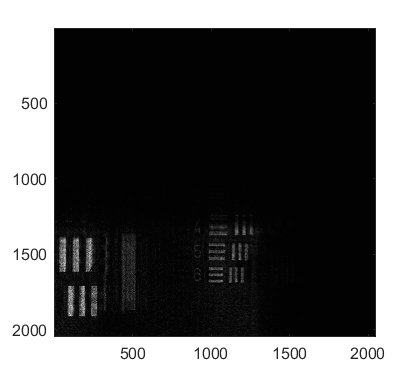

ImagenFinal4=(abs((((c3))).^2));
ImagenFinal4=imresize(ImagenFinal4,2048/919);
imagesc(ImagenFinal4)